# Event-driven simulation model

This script is used to produce Waiting time results using the event-driven model. The results will be compared with the waiting time results calculated by the `CloudEdgeAssetsOptimizer`. 

Simulink model of data processing in the cloud was developed using SimEvents toolbox. The model is saved in the EventDrivenSimulationModel.slx file. 

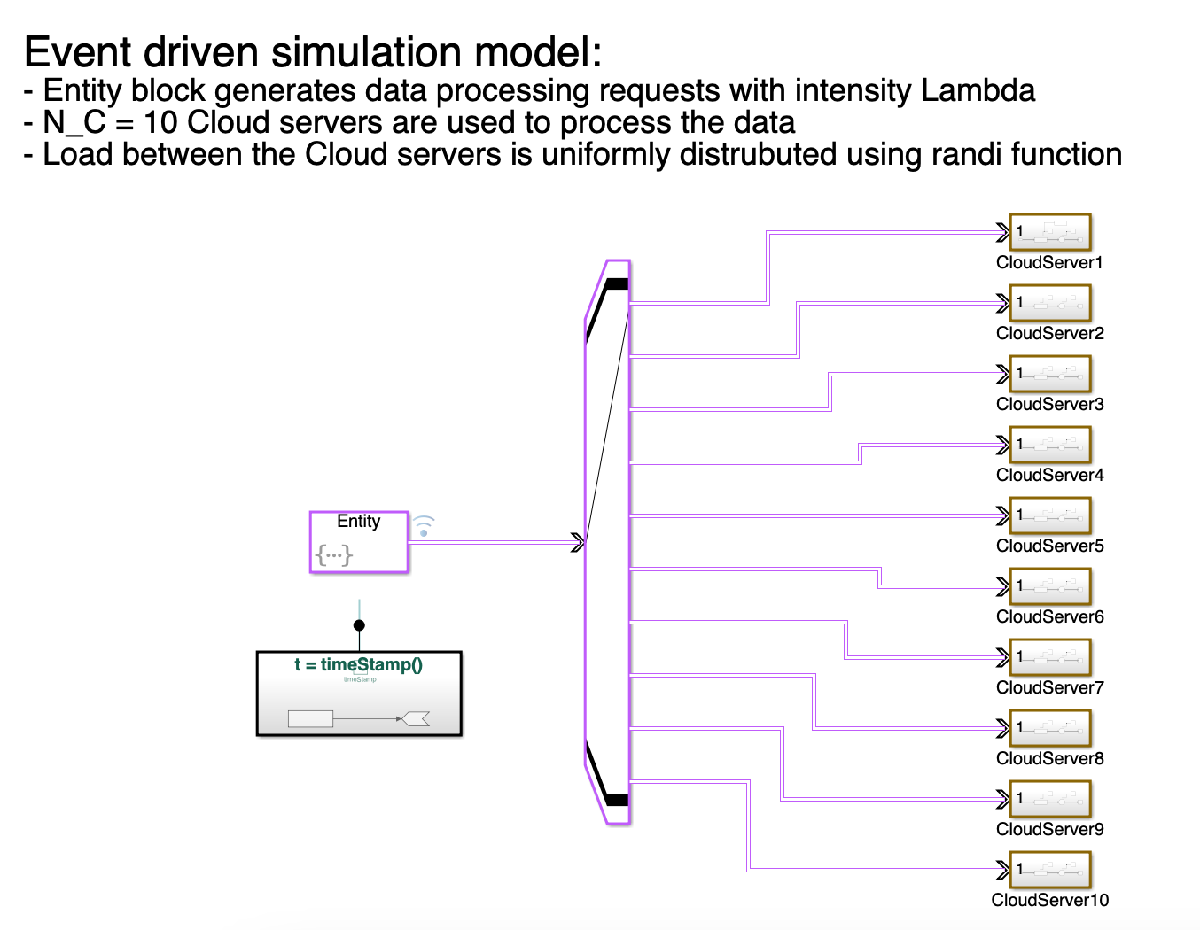

clear; close all;
ModelingDur = 1000;
Lambda = 50:25:350; 
Ncycle = length(Lambda);

mean_T_C_s = 100; % s
std_T_C_s = 50; % s

mean_T_C = mean_T_C_s / 3600;
std_T_C = std_T_C_s / 3600;

W_C = zeros(3,Ncycle);
tic
for qsys = 1:3
    % mm1: qsys = 1; mg1: qsys = 2; md1: qsys = 3
    for i = 1:Ncycle
        % tic
        lambda = Lambda(i);
        rng('shuffle');
        sim('EventDrivenSimulationModel');
        Wq_C = mean(cloud_wait_in_queue.Data);
        W_C(qsys,i) = (mean_T_C+Wq_C)*3600;
        % toc
    end
end
toc

Elapsed time is 595.927025 seconds.


Results are saved in CSV file. The file is used in example5_qsystem_vs_SimEvents.py to compare the results obtained by the Analytical model used in the CloudEdgeAssetsOptimizer.

W_C_mm1 = W_C(1,:);
W_C_mg1 = W_C(2,:);
W_C_md1 = W_C(3,:);
A = table(Lambda',W_C_mm1',W_C_mg1',W_C_md1','VariableNames',{'Lambda','W_C_mm1','W_C_mg1','W_C_md1'});
writetable(A,'event_driven_model_results_simtime1000h.csv','WriteVariableNames', true)

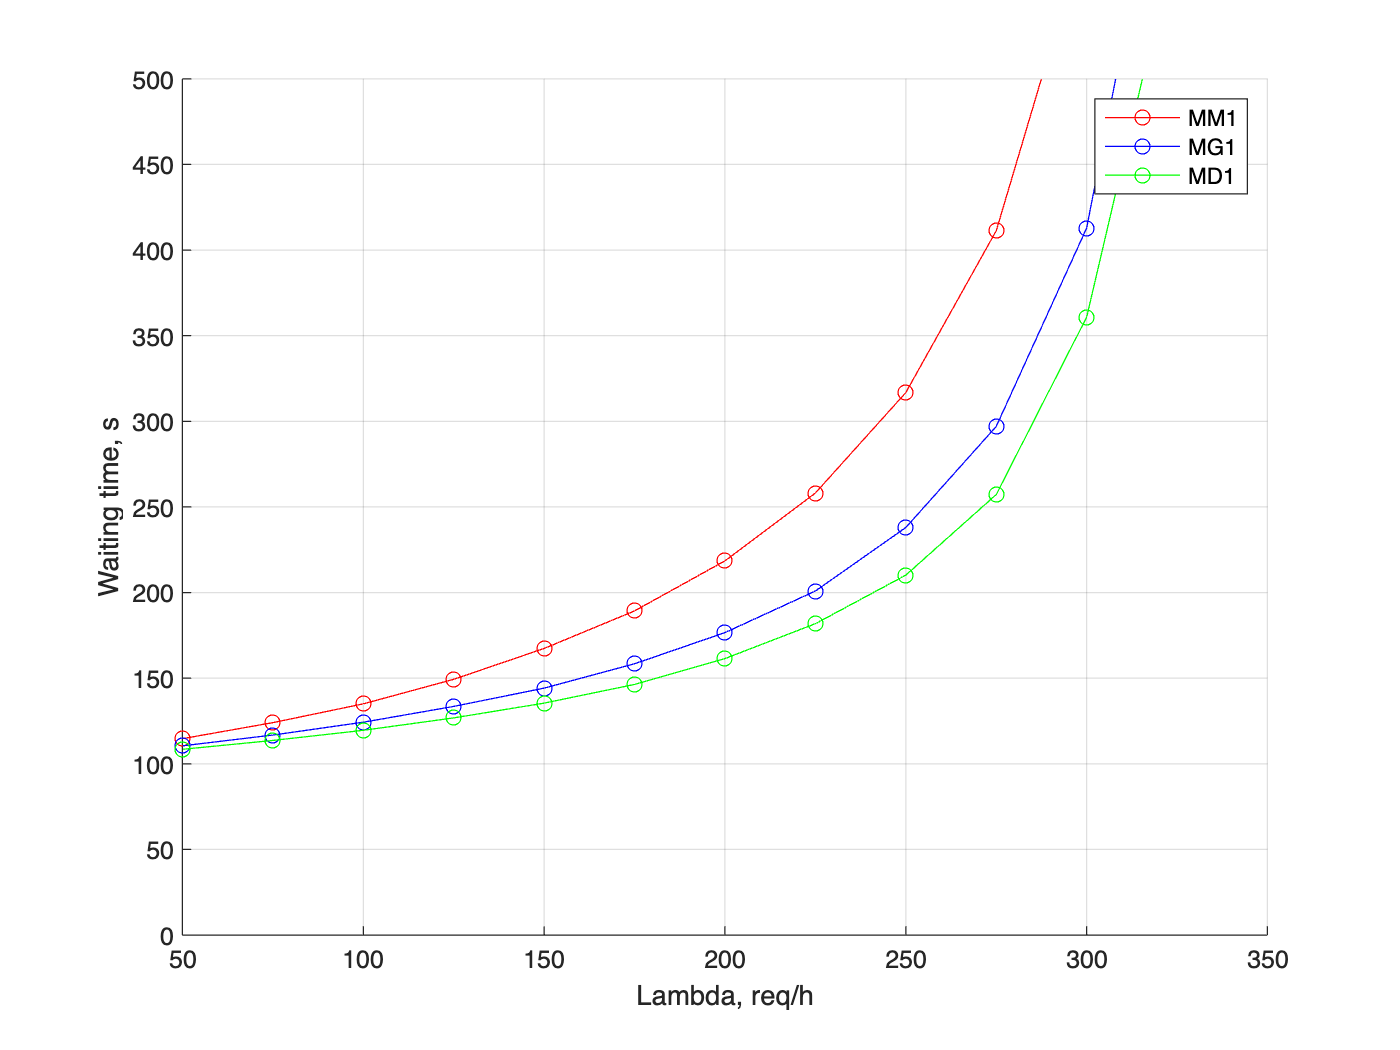

figure()
hold on
plot(Lambda,W_C(1,:),'r-o') % mm1
plot(Lambda,W_C(2,:),'b-o') % mg1
plot(Lambda,W_C(3,:),'g-o') % md1
ylim([0,500])
legend('MM1','MG1','MD1')
xlabel('Lambda, req/h')
ylabel('Waiting time, s')
grid on